Leo los datos extraídos de la respuesta al esclón

step_resp = open('WA000001.CSV')

step_resp = struct with fields:
        data: [30000×4 double]
    textdata: {10×6 cell}


step_t = step_resp.data(:,2);
step_y = step_resp.data(:,3);
step_u = step_resp.data(:,4);
ts = 0.0004;

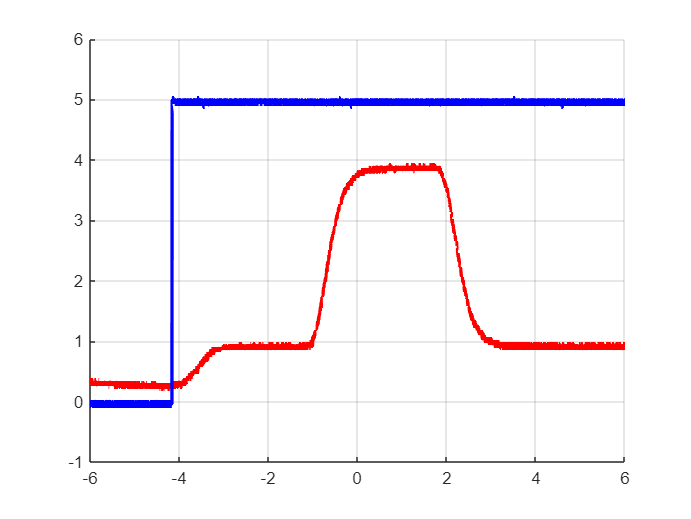

figure();
grid on; hold on;

plot(step_t, step_y, 'r', 'LineWidth', 2);
plot(step_t, step_u, 'b', 'LineWidth', 2);

Proceso la información para quedarme solo con el escalón de subida

step_u

step_u =    -0.0396
   -0.0396
   -0.0792
   -0.0396
   -0.0396
         0
   -0.0396
   -0.0396
   -0.0396
   -0.0792



rising_index = 4601 + length(0:ts:3)

rising_index = 12102

stop_index = rising_index + length(0:ts:3)

stop_index = 19603

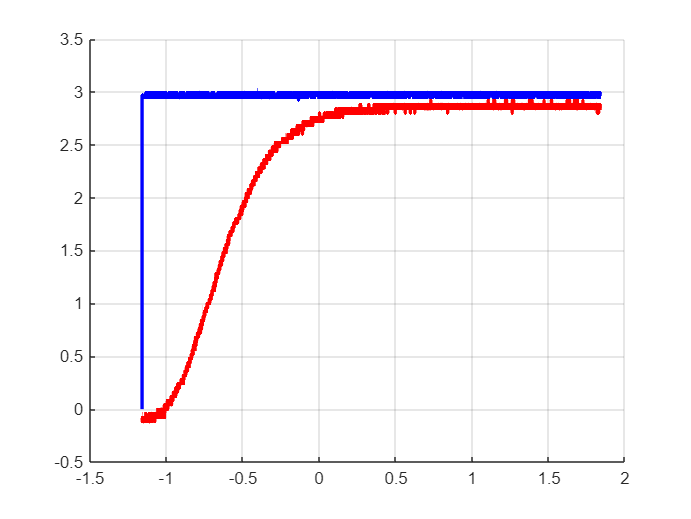


esc_y = step_y(rising_index:stop_index);
esc_u = step_u(rising_index:stop_index); esc_u(1) = 0;
esc_t = step_t(rising_index:stop_index);

esc_y=esc_y-1;
esc_u=esc_u*3/5;

figure();
grid on; hold on;

plot(esc_t, esc_y, 'r', 'LineWidth', 2);
plot(esc_t, esc_u, 'b', 'LineWidth', 2);